## **Projeto de Eletromagnetismo**

#### **Por: Beni Kracochansky, Murilo Menezes e Rodrigo Mattar**

%% 1. Modelando a antena.

ant = spiralArchimedean("InnerRadius", 0.3, "OuterRadius", 0.4, "NumArms", 1, "Tilt",90,"TiltAxis", 'Y', "Turn", 5)

ant =   spiralArchimedean with properties:

             NumArms: 1
               Turns: 5
         InnerRadius: 0.3000
         OuterRadius: 0.4000
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


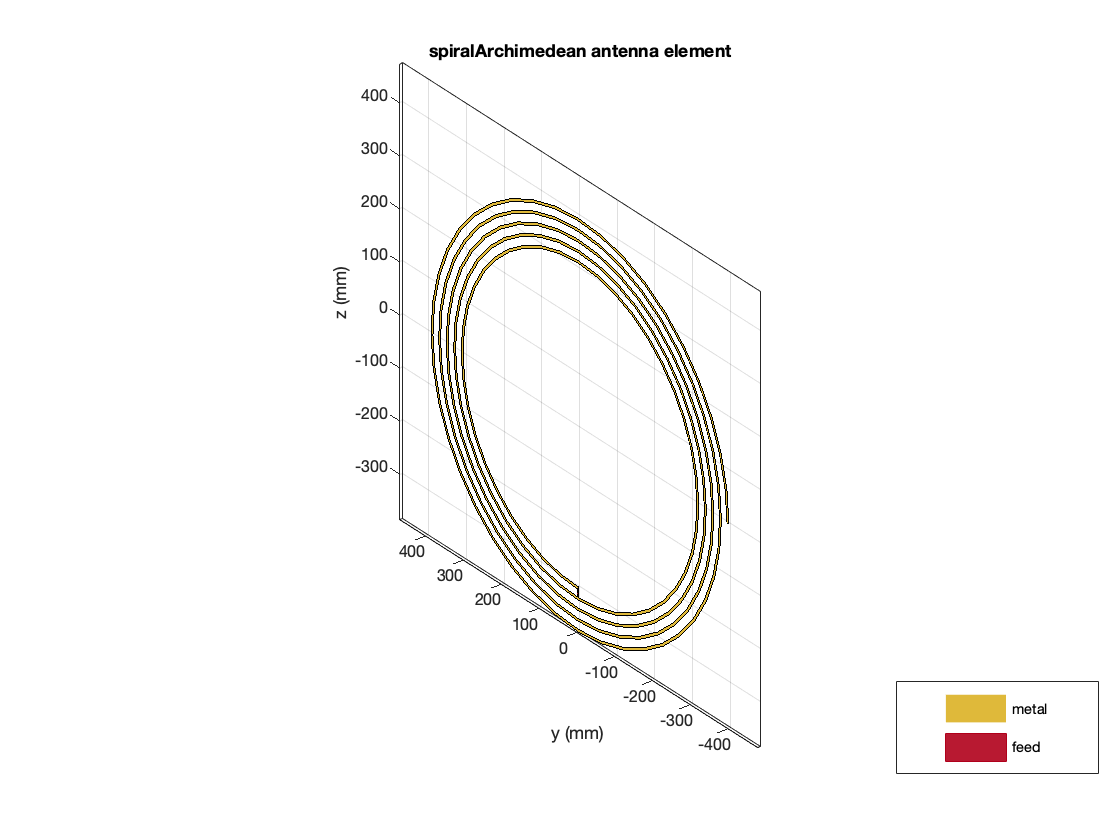

show(ant)

%% 2. Calculando a impedância da antena.

freq = linspace(0.6e6,1.6e7,100)

freq = 	1.0e+07 *

    0.0600    0.0756    0.0911    0.1067    0.1222    0.1378    0.1533    0.1689    0.1844    0.2000    0.2156    0.2311    0.2467    0.2622    0.2778    0.2933    0.3089    0.3244    0.3400    0.3556    0.3711    0.3867    0.4022    0.4178    0.4333    0.4489    0.4644    0.4800    0.4956    0.5111    0.5267    0.5422    0.5578    0.5733    0.5889    0.6044    0.6200    0.6356    0.6511    0.6667    0.6822    0.6978    0.7133    0.7289    0.7444    0.7600    0.7756    0.7911    0.8067    0.8222


Z = impedance(ant,freq)

Z = 	1.0e+04 *

   0.0000 + 0.0008i   0.0000 + 0.0010i   0.0000 + 0.0013i   0.0000 + 0.0015i   0.0000 + 0.0017i   0.0000 + 0.0019i   0.0000 + 0.0021i   0.0000 + 0.0024i   0.0000 + 0.0026i   0.0000 + 0.0028i   0.0000 + 0.0031i   0.0000 + 0.0033i   0.0000 + 0.0035i   0.0000 + 0.0038i   0.0000 + 0.0040i   0.0000 + 0.0043i   0.0000 + 0.0045i   0.0000 + 0.0048i   0.0000 + 0.0050i   0.0000 + 0.0053i   0.0000 + 0.0056i   0.0000 + 0.0058i   0.0000 + 0.0061i   0.0000 + 0.0064i   0.0000 + 0.0067i   0.0000 + 0.0070i   0.0000 + 0.0074i   0.0000 + 0.0077i   0.0000 + 0.0081i   0.0000 + 0.0084i   0.0000 + 0.0088i   0.0000 + 0.0092i   0.0000 + 0.0097i   0.0000 + 0.0101i   0.0000 + 0.0106i   0.0000 + 0.0112i   0.0000 + 0.0118i   0.0000 + 0.0124i   0.0000 + 0.0131i   0.0000 + 0.0139i   0.0000 + 0.0148i   0.0000 + 0.0159i   0.0000 + 0.0171i   0.0000 + 0.0185i   0.0000 + 0.0203i   0.0000 + 0.0225i   0.0000 + 0.0254i   0.0000 + 0.0295i   0.0000 + 0.0355i   0.0000 + 0.0454i


comp = imag(Z)

comp = 	1.0e+04 *

    0.0008    0.0010    0.0013    0.0015    0.0017    0.0019    0.0021    0.0024    0.0026    0.0028    0.0031    0.0033    0.0035    0.0038    0.0040    0.0043    0.0045    0.0048    0.0050    0.0053    0.0056    0.0058    0.0061    0.0064    0.0067    0.0070    0.0074    0.0077    0.0081    0.0084    0.0088    0.0092    0.0097    0.0101    0.0106    0.0112    0.0118    0.0124    0.0131    0.0139    0.0148    0.0159    0.0171    0.0185    0.0203    0.0225    0.0254    0.0295    0.0355    0.0454


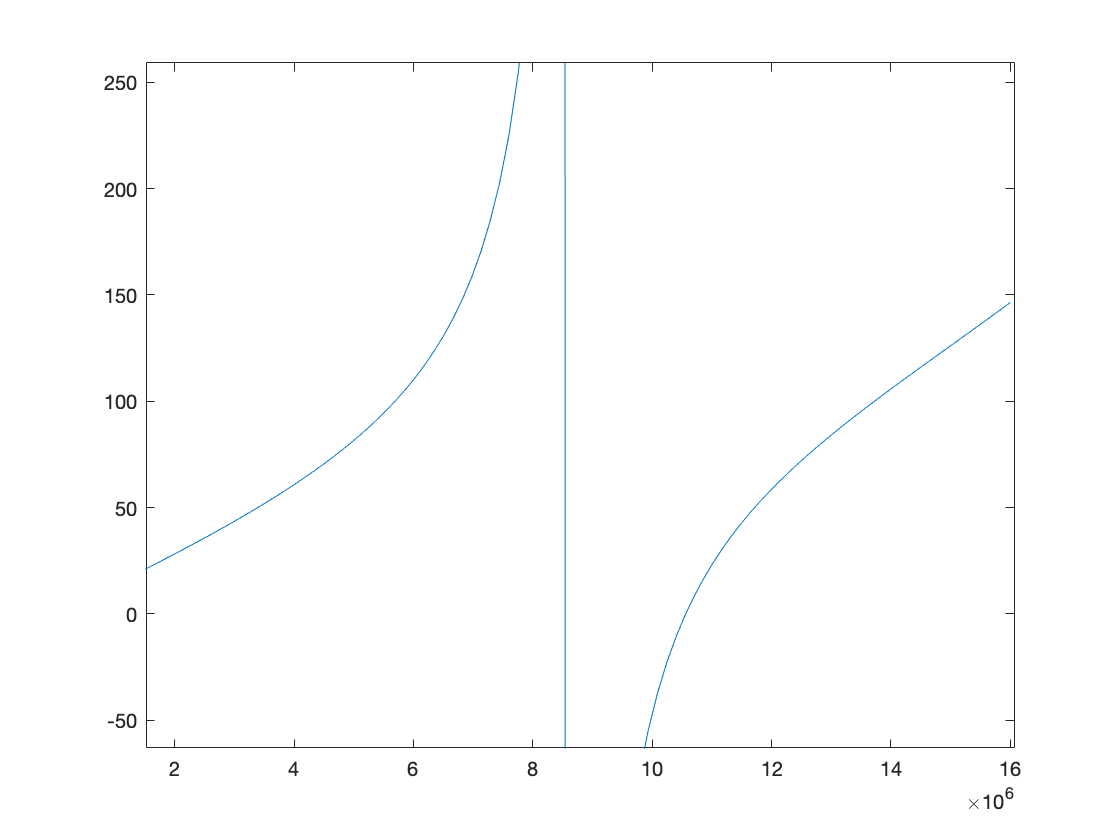


plot(freq, comp)
ylim([-100,100])

xlim([1517480 16062935])
ylim([-63 259])


%% Obtendo frequências.
wc = 8.5e6

wc = 8500000

freq_outra = 10.5e6

freq_outra = 10500000

% 3. Modelando antena receptora.

rec = spiralArchimedean("InnerRadius", 0.3, "OuterRadius", 0.4, "NumArms", 1, "Tilt",90,"TiltAxis", 'Y', "Turn", 5)

rec =   spiralArchimedean with properties:

             NumArms: 1
               Turns: 5
         InnerRadius: 0.3000
         OuterRadius: 0.4000
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


la = linearArray("Element", [ant, rec])

la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 2
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


la.ElementSpacing = 0.1

la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


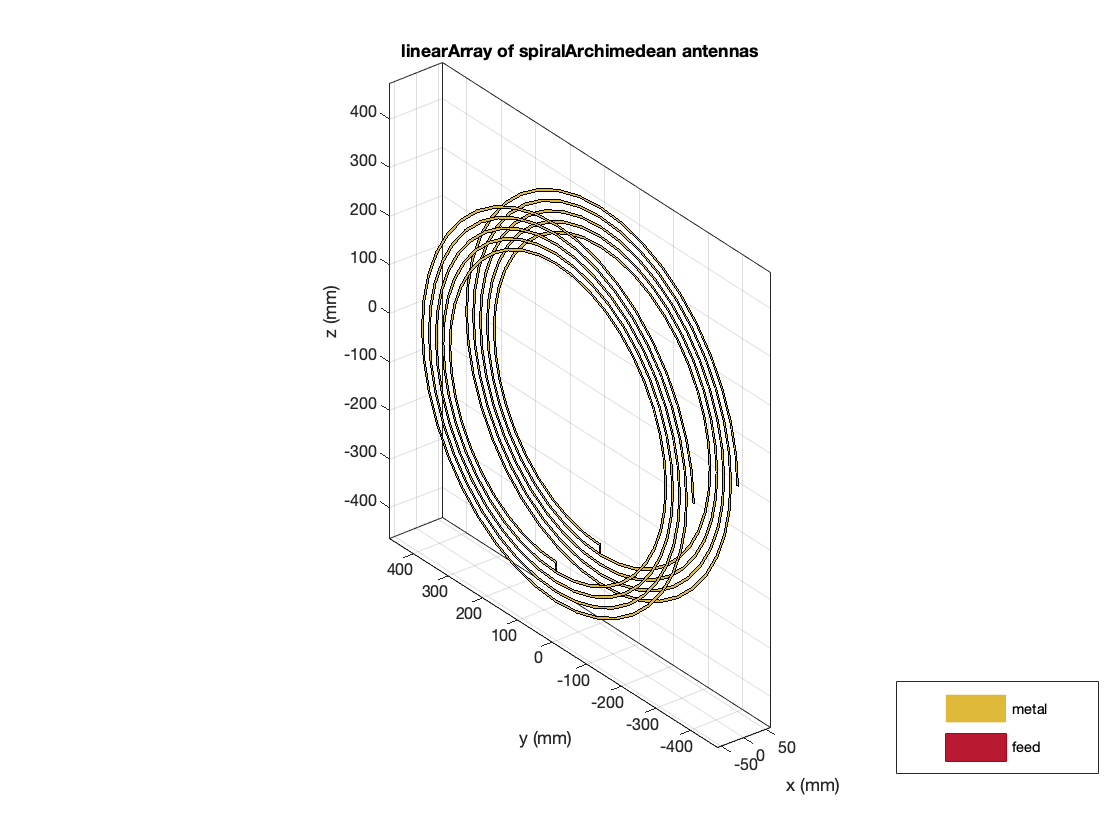

show(la)

% 4. Simulando acoplamento.
% 5. Visualizando o ganho.


cont = 1

cont = 1

la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


grafico =     0.0736    0.0916    0.1088    0.1251    0.1406    0.1551    0.1686    0.1812    0.1928    0.2034    0.2132    0.2221    0.2302    0.2376    0.2444    0.2505    0.2561    0.2613    0.2660    0.2705    0.2746    0.2785    0.2823    0.2859    0.2895    0.2930    0.2966    0.3003    0.3041    0.3081    0.3123    0.3169    0.3217    0.3270    0.3328    0.3392    0.3462    0.3539    0.3624    0.3720    0.3827    0.3946    0.4080    0.4232    0.4403    0.4598    0.4819    0.5071    0.5360    0.5690


cont = 2

rf1 =   Line (abs(S_{21})) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


grafico =     0.0736    0.0916    0.1088    0.1251    0.1406    0.1551    0.1686    0.1812    0.1928    0.2034    0.2132    0.2221    0.2302    0.2376    0.2444    0.2505    0.2561    0.2613    0.2660    0.2705    0.2746    0.2785    0.2823    0.2859    0.2895    0.2930    0.2966    0.3003    0.3041    0.3081    0.3123    0.3169    0.3217    0.3270    0.3328    0.3392    0.3462    0.3539    0.3624    0.3720    0.3827    0.3946    0.4080    0.4232    0.4403    0.4598    0.4819    0.5071    0.5360    0.5690
    0.0400    0.0497    0.0591    0.0681    0.0766    0.0846    0.0921    0.0992    0.1057    0.1117    0.1172    0.1223    0.1270    0.1313    0.1353    0.1389    0.1423    0.1454    0.1484    0.1512    0.1538    0.1563    0.1588    0.1613    0.1637    0.1662    0.1687    0.1714    0.1741    0.1770    0.1801    0.1835    0.1871    0.1910    0.1953    0.2000    0.2051    0.2109    0.2173    0.2244    0.2323    0.2412    0.2513    0.2627    0.2757    0.2905    0.3074    0.3270    0.349

cont = 3

rf1 =   Line (abs(S_{21})) with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


grafico =     0.0736    0.0916    0.1088    0.1251    0.1406    0.1551    0.1686    0.1812    0.1928    0.2034    0.2132    0.2221    0.2302    0.2376    0.2444    0.2505    0.2561    0.2613    0.2660    0.2705    0.2746    0.2785    0.2823    0.2859    0.2895    0.2930    0.2966    0.3003    0.3041    0.3081    0.3123    0.3169    0.3217    0.3270    0.3328    0.3392    0.3462    0.3539    0.3624    0.3720    0.3827    0.3946    0.4080    0.4232    0.4403    0.4598    0.4819    0.5071    0.5360    0.5690
    0.0400    0.0497    0.0591    0.0681    0.0766    0.0846    0.0921    0.0992    0.1057    0.1117    0.1172    0.1223    0.1270    0.1313    0.1353    0.1389    0.1423    0.1454    0.1484    0.1512    0.1538    0.1563    0.1588    0.1613    0.1637    0.1662    0.1687    0.1714    0.1741    0.1770    0.1801    0.1835    0.1871    0.1910    0.1953    0.2000    0.2051    0.2109    0.2173    0.2244    0.2323    0.2412    0.2513    0.2627    0.2757    0.2905    0.3074    0.3270    0.349

cont = 4

rf1 =   Line (abs(S_{21})) with properties:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


grafico =     0.0736    0.0916    0.1088    0.1251    0.1406    0.1551    0.1686    0.1812    0.1928    0.2034    0.2132    0.2221    0.2302    0.2376    0.2444    0.2505    0.2561    0.2613    0.2660    0.2705    0.2746    0.2785    0.2823    0.2859    0.2895    0.2930    0.2966    0.3003    0.3041    0.3081    0.3123    0.3169    0.3217    0.3270    0.3328    0.3392    0.3462    0.3539    0.3624    0.3720    0.3827    0.3946    0.4080    0.4232    0.4403    0.4598    0.4819    0.5071    0.5360    0.5690
    0.0400    0.0497    0.0591    0.0681    0.0766    0.0846    0.0921    0.0992    0.1057    0.1117    0.1172    0.1223    0.1270    0.1313    0.1353    0.1389    0.1423    0.1454    0.1484    0.1512    0.1538    0.1563    0.1588    0.1613    0.1637    0.1662    0.1687    0.1714    0.1741    0.1770    0.1801    0.1835    0.1871    0.1910    0.1953    0.2000    0.2051    0.2109    0.2173    0.2244    0.2323    0.2412    0.2513    0.2627    0.2757    0.2905    0.3074    0.3270    0.349

cont = 5

rf1 =   Line (abs(S_{21})) with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.5000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


grafico =     0.0736    0.0916    0.1088    0.1251    0.1406    0.1551    0.1686    0.1812    0.1928    0.2034    0.2132    0.2221    0.2302    0.2376    0.2444    0.2505    0.2561    0.2613    0.2660    0.2705    0.2746    0.2785    0.2823    0.2859    0.2895    0.2930    0.2966    0.3003    0.3041    0.3081    0.3123    0.3169    0.3217    0.3270    0.3328    0.3392    0.3462    0.3539    0.3624    0.3720    0.3827    0.3946    0.4080    0.4232    0.4403    0.4598    0.4819    0.5071    0.5360    0.5690
    0.0400    0.0497    0.0591    0.0681    0.0766    0.0846    0.0921    0.0992    0.1057    0.1117    0.1172    0.1223    0.1270    0.1313    0.1353    0.1389    0.1423    0.1454    0.1484    0.1512    0.1538    0.1563    0.1588    0.1613    0.1637    0.1662    0.1687    0.1714    0.1741    0.1770    0.1801    0.1835    0.1871    0.1910    0.1953    0.2000    0.2051    0.2109    0.2173    0.2244    0.2323    0.2412    0.2513    0.2627    0.2757    0.2905    0.3074    0.3270    0.349

cont = 6

rf1 =   Line (abs(S_{21})) with properties:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


la =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.6000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


grafico =     0.0736    0.0916    0.1088    0.1251    0.1406    0.1551    0.1686    0.1812    0.1928    0.2034    0.2132    0.2221    0.2302    0.2376    0.2444    0.2505    0.2561    0.2613    0.2660    0.2705    0.2746    0.2785    0.2823    0.2859    0.2895    0.2930    0.2966    0.3003    0.3041    0.3081    0.3123    0.3169    0.3217    0.3270    0.3328    0.3392    0.3462    0.3539    0.3624    0.3720    0.3827    0.3946    0.4080    0.4232    0.4403    0.4598    0.4819    0.5071    0.5360    0.5690
    0.0400    0.0497    0.0591    0.0681    0.0766    0.0846    0.0921    0.0992    0.1057    0.1117    0.1172    0.1223    0.1270    0.1313    0.1353    0.1389    0.1423    0.1454    0.1484    0.1512    0.1538    0.1563    0.1588    0.1613    0.1637    0.1662    0.1687    0.1714    0.1741    0.1770    0.1801    0.1835    0.1871    0.1910    0.1953    0.2000    0.2051    0.2109    0.2173    0.2244    0.2323    0.2412    0.2513    0.2627    0.2757    0.2905    0.3074    0.3270    0.349

cont = 7

rf1 =   Line (abs(S_{21})) with properties:

              Color: [0.3010 0.7450 0.9330]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


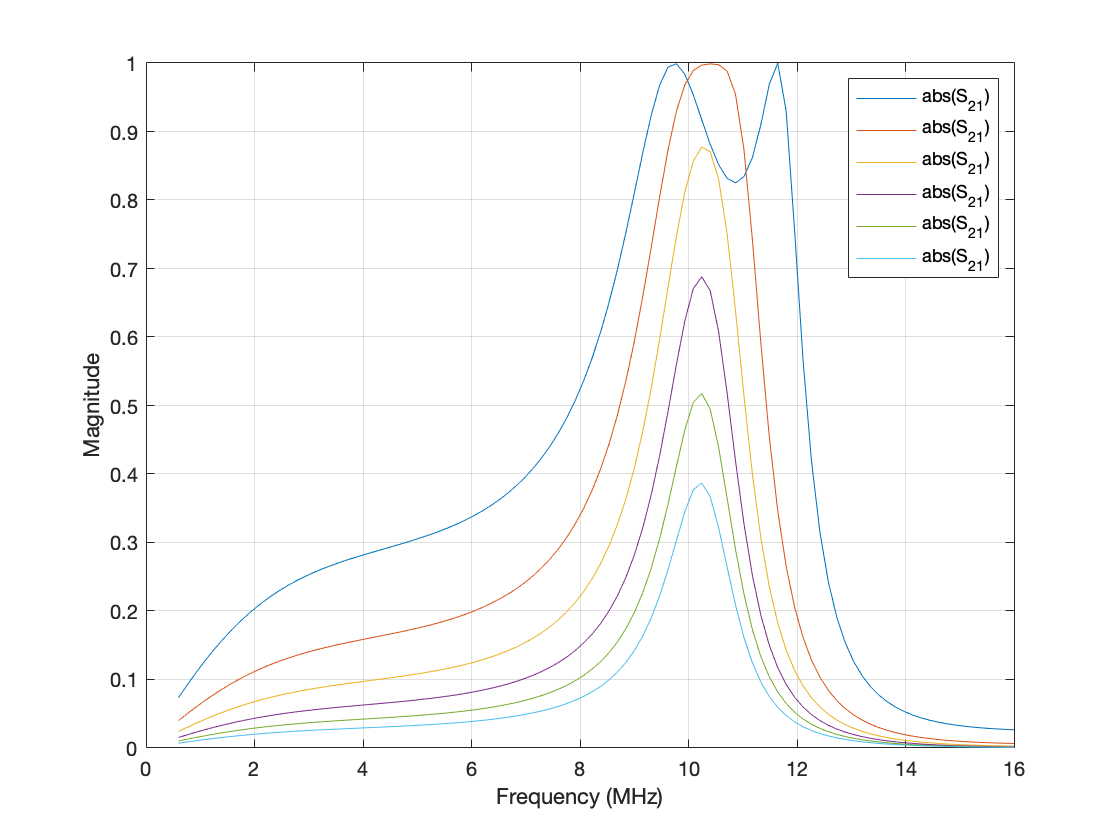

for d=0.1:0.1:0.6
    la.ElementSpacing = d
    ganhos = sparameters(la,freq)
    grafico(cont,:) = abs(rfparam(ganhos, 2, 1))
    cont = cont + 1
    rf1 = rfplot(ganhos, 2,1, 'd')
    hold on
end


%% Quanto maior a distância, menor o ganho, pois é menor o acoplamento entre as duas antenas.

% 6. Visualização 3D

dist = [0.1 0.2 0.3 0.4 0.5 0.6]

dist =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000



[X,Y] = meshgrid(freq/1e6,dist)

X =     0.6000    0.7556    0.9111    1.0667    1.2222    1.3778    1.5333    1.6889    1.8444    2.0000    2.1556    2.3111    2.4667    2.6222    2.7778    2.9333    3.0889    3.2444    3.4000    3.5556    3.7111    3.8667    4.0222    4.1778    4.3333    4.4889    4.6444    4.8000    4.9556    5.1111    5.2667    5.4222    5.5778    5.7333    5.8889    6.0444    6.2000    6.3556    6.5111    6.6667    6.8222    6.9778    7.1333    7.2889    7.4444    7.6000    7.7556    7.9111    8.0667    8.2222
    0.6000    0.7556    0.9111    1.0667    1.2222    1.3778    1.5333    1.6889    1.8444    2.0000    2.1556    2.3111    2.4667    2.6222    2.7778    2.9333    3.0889    3.2444    3.4000    3.5556    3.7111    3.8667    4.0222    4.1778    4.3333    4.4889    4.6444    4.8000    4.9556    5.1111    5.2667    5.4222    5.5778    5.7333    5.8889    6.0444    6.2000    6.3556    6.5111    6.6667    6.8222    6.9778    7.1333    7.2889    7.4444    7.6000    7.7556    7.9111    8.0667    8

Y =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0

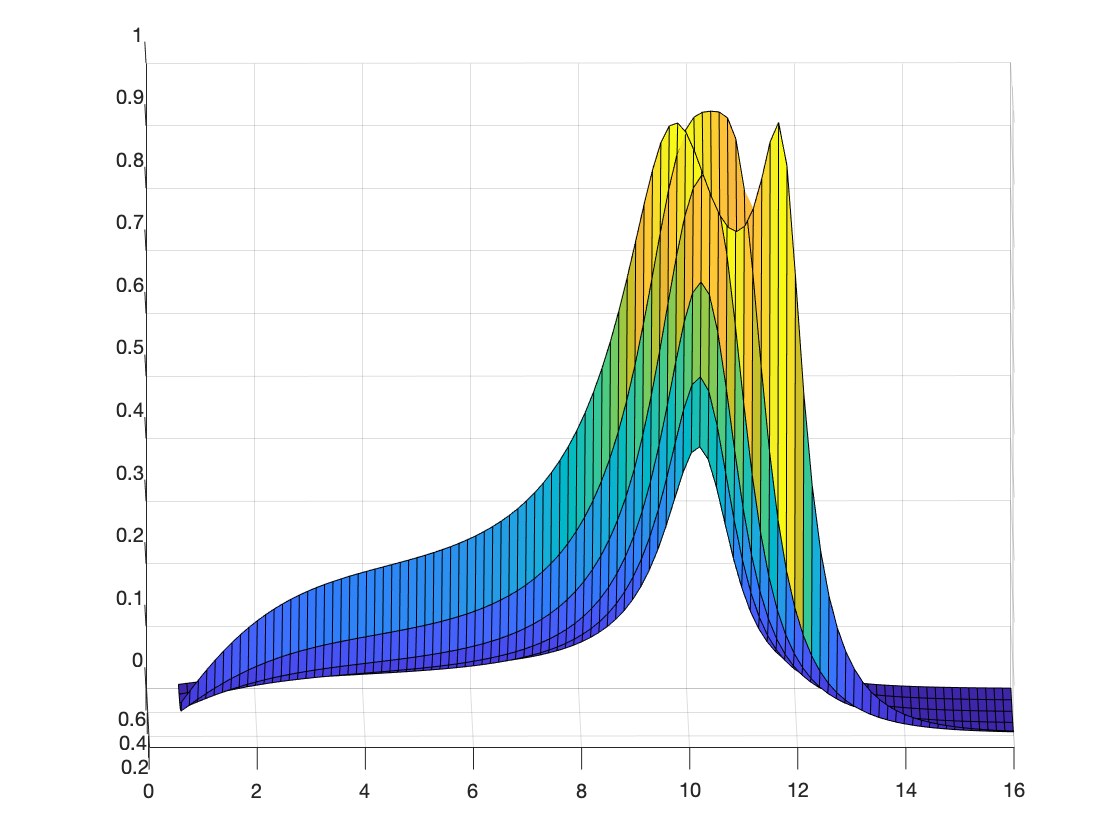


figure()
surf(X,Y,grafico)

xlim([0.0 16.0])
ylim([0.100 0.600])
zlim([0.000 1.000])

cont = 1
for d=0.1:0.1:0.6
    la.ElementSpacing = d
    ganhos = sparameters(la,freq)
    grafico(cont,:) = abs(rfparam(ganhos, 2, 1))
    cont = cont + 1
    rf1 = rfplot(ganhos, 2,1, 'd')
    hold on
end

frequencia = 	1.0e+07 *

    0.0600    0.0756    0.0911    0.1067    0.1222    0.1378    0.1533    0.1689    0.1844    0.2000    0.2156    0.2311    0.2467    0.2622    0.2778    0.2933    0.3089    0.3244    0.3400    0.3556    0.3711    0.3867    0.4022    0.4178    0.4333    0.4489    0.4644    0.4800    0.4956    0.5111    0.5267    0.5422    0.5578    0.5733    0.5889    0.6044    0.6200    0.6356    0.6511    0.6667    0.6822    0.6978    0.7133    0.7289    0.7444    0.7600    0.7756    0.7911    0.8067    0.8222


dist =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000


ar =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 2
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ar =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


g =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


g_z =    0.0238 + 0.0697i
   0.0368 + 0.0839i
   0.0517 + 0.0957i
   0.0681 + 0.1050i
   0.0856 + 0.1115i
   0.1036 + 0.1154i
   0.1218 + 0.1167i
   0.1397 + 0.1154i
   0.1569 + 0.1119i
   0.1734 + 0.1064i


Unrecognized function or variable 'col'.